# **Offshroe pile-UQlink with ICFEP**

**Main_Pile.mlx: Main document to excute the program**

**DataInput.m: Probabilistic input parameters**

**Pile.t.tpl: template file for FE running, argument format： <X00001>, <X00002>,...**

**ReadOutput.m: read output from .t file and save FE results to file in case collaspse during running**

**Wrapper.m: Link ICFEP with uqlab**

## **1 - INITIALIZE UQLAB**

clearvars;clear all;clc
rng(3,'twister')
addpath('E:\tl\UQLab_Rel2.0.0\core') % UQLAB location
addpath([pwd() '\Codes'])
uqlab

Copyright 2013-2022, Stefano Marelli and Bruno Sudret, all rights reserved.
This is UQLab, version 2.0
UQLab is distributed under the BSD 3-clause open source license available at: 
E:\tl\UQLab_Rel2.0.0\LICENSE.

To request special permissions, please contact:
  - Stefano Marelli (<a href="mailto:marelli@ibk.baug.ethz.ch">marelli@ibk.baug.ethz.ch</a>).

Useful commands to get started with UQLab:
uqlab -doc           - Access the available documentation
uqlab -help          - Additional help on how to get started with UQLab
uq_citation help   - Information on how to cite UQLab in publications
uqlab -license       - Display UQLab license information



global sampleNumber
sampleNumber = 0;

## 2 -Wrapper with ICFEP

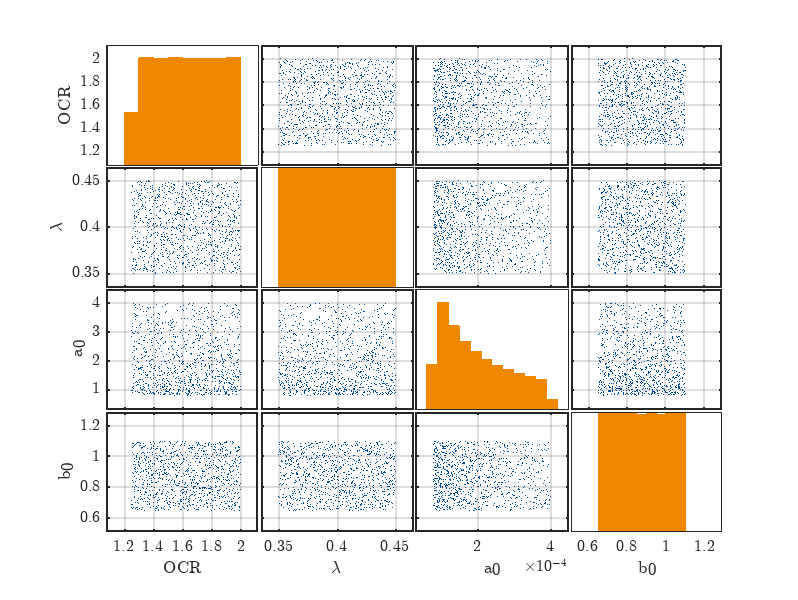

%Probabilistic input parameters
Input_Name    =   {'OCR',      '\lambda',     'a_{0}',      'b_{0}'};  
parameter1      =   [1.25          0.35        8.0E-5          0.65 ];
parameter2      =   [2.00          0.45        4.0E-4          1.10 ]; 
type =              ["uniform",  "uniform",  "loguniform",    "uniform",];

%Number of variables: N_input
N_input = length(Input_Name);

% Create the INPUT object
myInput = DataInput(Input_Name, parameter1, parameter2, type); 

% Display input
uq_display(myInput) 

% Wrapper ICFEP with UQLink:
name = 'ICFEP_UQLINK';
myUQLinkModel = Wrapper(name);

## 3 Sampling and runing



%sample from input space using LHS
% Number of samples/Runs
N_FE_RUN = 2;
X_Sample = uq_getSample(N_FE_RUN,'LHS');


%run the FE models
[~] = uq_evalModel(myUQLinkModel,X_Sample);

list001 is finished!
list002 is finished!


## 4 Post process output

extract the data from .mat file from FE_Results file

**Sum_output1**:sumarry for output 1             

**Sum_output2**:sumarry for output 2             

**coord1**: coordinate for output 1            

**coord2**: coordinate for output 2             

%raw output data before post processsing
Raw_Y_Sum_1 = {};
Raw_Y_Sum_2 = [];

% define the file .mat file stored
subfolder = 'FE_Result';

% get how many runs successfully saved in file 'FE_Result'
dirList = dir([pwd() '\FE_Result']);
N_FE_RUN = length(dirList) - 2;

%loop to extract data from XXX.mat file
for k = 1: N_FE_RUN
    filename  = ['list', sprintf('%03d', k),'.mat'];
    load([fullfile(subfolder,filename)]);
    Raw_Y_Sum_1{k} = output1;
    Raw_Y_Sum_2 = output2;
end

%get total increment number in a FE run
N_incre_total = size(output1,2);


%initial value for summary output1/2
Sum_output1 = cell(1,N_incre_total);
Sum_output2 = [];

%initial stage number
k = 0;
for j = 1:N_incre_total
    k = k+1;
    stageData1 = [];
    for i= 1:N_FE_RUN
        Y1_i = Raw_Y_Sum_1{i};
        tempStage1 = Y1_i(:,j);
        stageData1 = [stageData1 tempStage1 ];
    end

    Sum_output1{j}= stageData1'; 
    Sum_output2 = output2;

end

save all the  result

save All_Results